# Handle Errors from Functions Running in the Background

This example shows how to use `afterEach` to handle errors from a function that runs in the background.

When computations for `Future` objects result in an error, by default, `afterEach` does not evaluate its function on the elements that failed. If you want to handle any errors, for example, when you have a user interface that you want to update, you can use the `PassFuture` argument. When you set `PassFuture` to `true`, MATLAB passes the `Future` object to the callback function. You can call `fetchOutputs` on it, process the outputs, and handle any possible errors.

Send a computation to the background using `parfeval`. The computation results in an error. You can view the error message using the `Error` property of the future.

errorFuture = parfeval(backgroundPool, ...
    @(n,k) factorial(n)/(factorial(k)*factorial(n-k)),1,4,8);
wait(errorFuture);
errorFuture.Error

If you use `afterEach` on a future that results in an error, the callback function is not evaluated. In the code below, MATLAB does not execute the `displayResult` function because the future errors.

afterEach(errorFuture,@displayResult,0);

Write a callback function to handle futures that result in errors. If the error property of the future variable is empty, the `handleError` helper function calls `fetchOutputs` on the future variable, and process its outputs. If the error property of the future variable is not empty, the `handleError` helper function displays an error dialog box.

function handleError(f)
fig = uifigure(Position=[100 100 425 275]);
if isempty(f.Error)
    output = fetchOutputs(f);
    message = strcat("Computation complete: Result = ",num2str(output));
    uialert(fig,message,"Sucess",Icon="success")
else
    message = "Computation failed!";
    uialert(fig,message,"Error",Icon="error")
end
end

Call `afterEach` with the `handleError` function and set `PassFuture` to `true`. 

afterEach(errorFuture,@handleError,0,PassFuture=true);

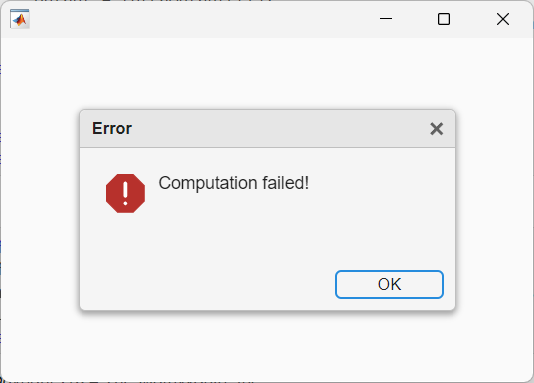

function displayResult(output)
fig = uifigure(Position=[100 100 425 275]);
message = strcat("Computation complete: Result = ",num2str(output));
uialert(fig,message,"Sucess",Icon="success")
end

*Copyright 2024 The MathWorks, Inc.*